clear ; close all ; clc;

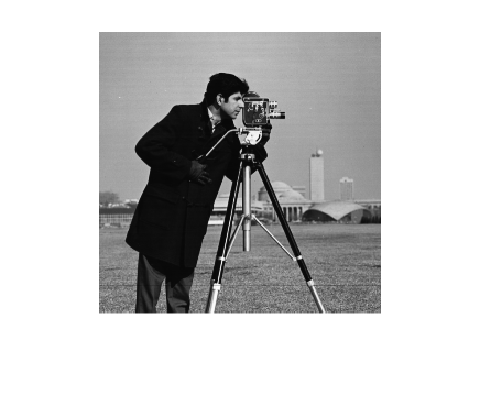

% read the input image 
I = imread('cameraman.tif');
I = imresize(I, [256 256]);
if size(I,3) == 3
    I = rgb2gray(I)
end
%I(50,50) = bitxor(I(50,50),1);
figure ; imshow(I) 

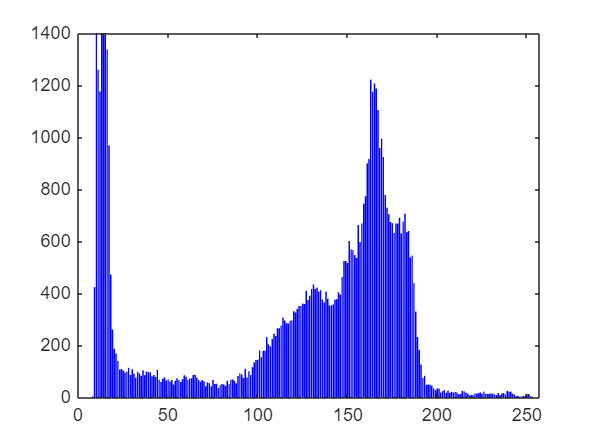

figure ; h00 = imhist(I) ; bar(h00 , 'blue') ; ylim([0 1400]) ; yticks(0:200:1400)

I_vec = double(I(:));

[p1,x01,p2,x02,H0] = derive_pwlcms_from_hmac(I_vec, 'QuantumKey2025', 0.00002);

% apply the confusion process:
PWLCM1 = pwlcm(p1  , x01 , 256^2);
[~, shufling_vec] = sort(PWLCM1); % get permutation index
shuffled_img_vec = I_vec(shufling_vec);
shuffled_img = reshape(uint8(shuffled_img_vec),256,256);
%figure ; imshow(shuffled_img);

% Apply bitwise XOR to generate the second PWLCM sequence;
I_xor = double(bitxor(uint8(shuffled_img_vec) , uint8(I_vec)));

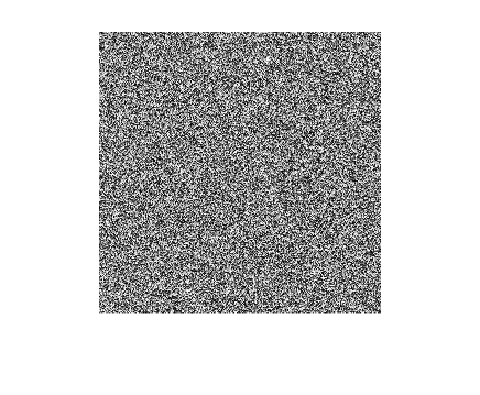

% Generate the second chaotic sequence and apply the diffusion process with
% modulo addition.
PWCLM2 = pwlcm(p2, x02 , 256^2);
diffusing_vec = (uint8(PWCLM2 * 255))';
Encrypted_vec = mod(double(shuffled_img_vec) + double(diffusing_vec) , 256);
Encrypted_img = reshape(Encrypted_vec , [256 256]);
figure ; imshow(uint8(Encrypted_img))

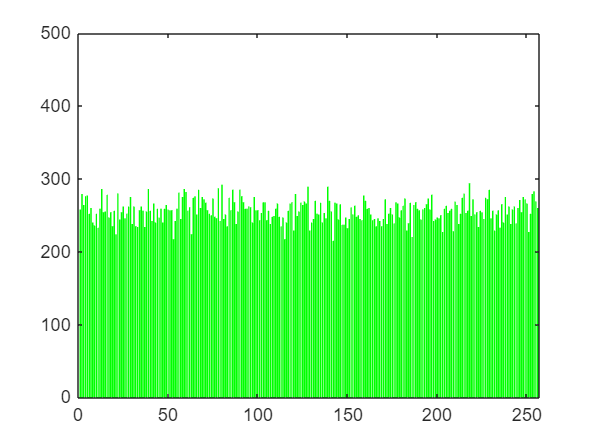

figure ; h1 = imhist(uint8(Encrypted_img)) ; bar(h1 , 'g') ; ylim([0 500])

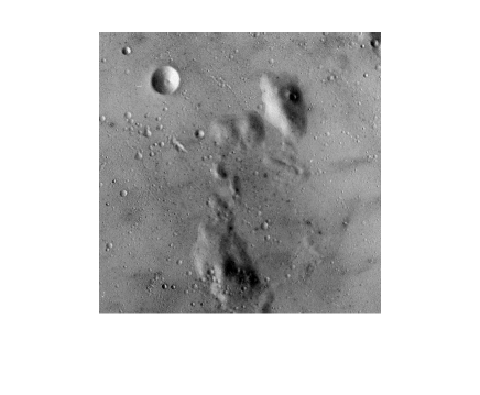

% Steganography part 
s  = 0.005;
cover = imread('moonsurface.tiff');
cover = imresize(cover , [256 256]);
if size(cover,3) == 3
    cover = rgb2gray(cover);
end
figure ; imshow(cover) ; 

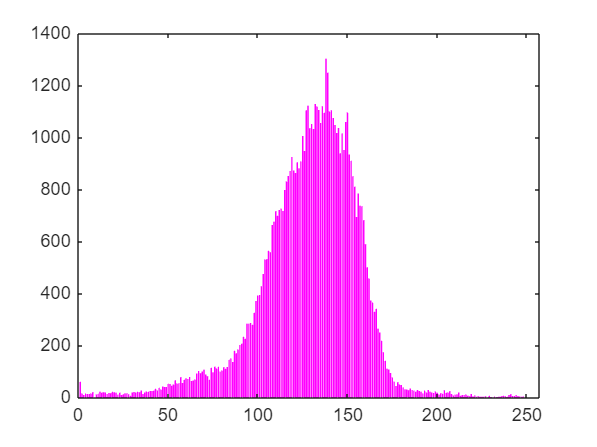

figure ; h0 = imhist(cover) ; bar(h0 , 'm')

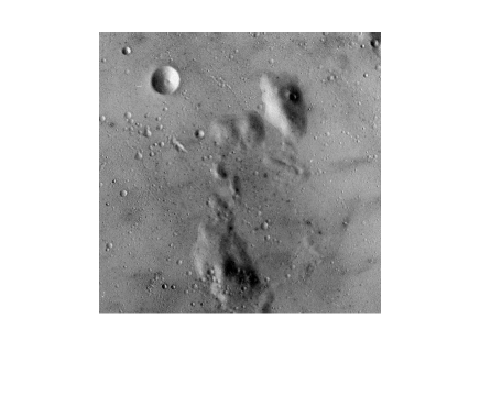


Stego_img = s .* Encrypted_img + (1-s) .* double(cover);
figure ; imshow(uint8(Stego_img)) ; 

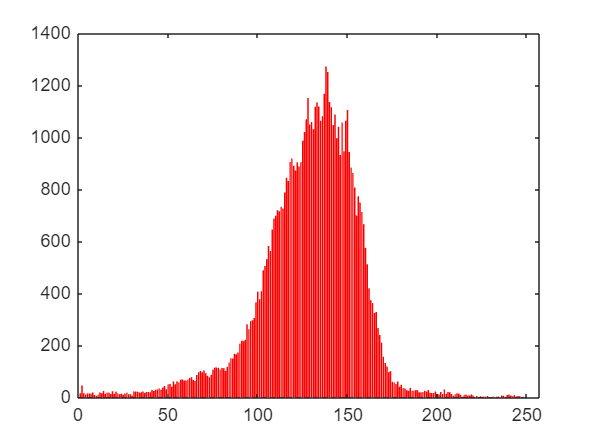

figure ; h = imhist(uint8(Stego_img) ); bar(h , 'r')

% Save keys for later use in decryption
keys = struct('p1', p1, 'x01', x01, 'p2', p2, 'x02', x02);
save('encryption_keys.mat', 'keys');
save('EncryptedImage_1.mat' , 'Encrypted_img')
save ('Stego_image.mat' , 'Stego_img')
imwrite(uint8(Encrypted_img) , 'Encrr.png')

[Horizontal_corr,Vertical_Corr,Diagonal_Corr] = evaluate_correlation(uint8(abs(cover)))

Horizontal_corr = 0.9020

Vertical_Corr = 0.9390

Diagonal_Corr = 0.9037

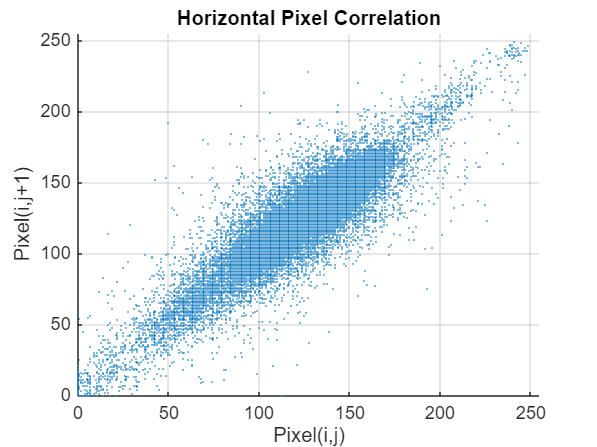

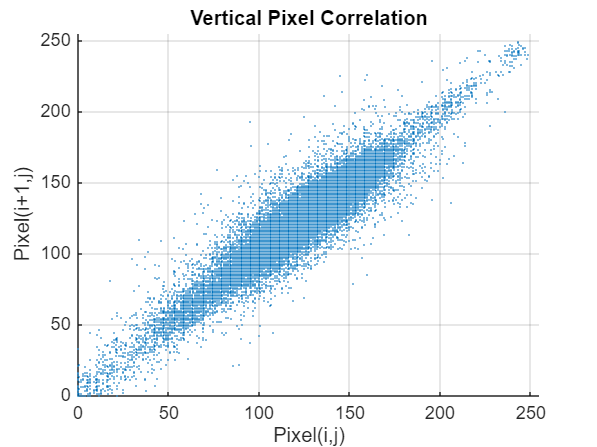

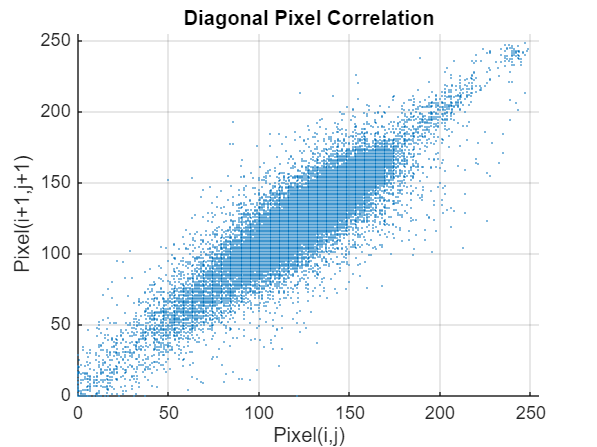

drawCorrelationScatter(uint8(abs(cover)))

entropy(uint8(cover))

ans = 6.7093

npcr = calculate_npcr(I,uint8(Encrypted_img))

NPCR: 99.64%


npcr = 99.6368

UACi = calculate_uaci(I,uint8(Encrypted_img))

UACi = 31.2607

PSNR = psnr(cover, uint8(Stego_img))

PSNR = 54.4258

SSI = ssim(cover, uint8(Stego_img))

SSI = 0.9989

function npcr_value = calculate_npcr(image1, image2)
    
    image1 = double(image1);
    image2 = double(image2);
    
    diff_image = image1 ~= image2;
    
    total_pixels = numel(image1);
    
    % Calculate the NPCR
    npcr_value = (sum(diff_image(:)) / total_pixels) * 100;
    
    % Display the NPCR value
    fprintf('NPCR: %.2f%%\n', npcr_value);
end
function uaci_value = calculate_uaci(image1, image2)
    
    image1 = double(image1);
    image2 = double(image2);
    diff = abs(image1 - image2);
  
    uaci_value = (sum(diff(:)) / (numel(image1) * 255)) * 100;
end

function drawCorrelationScatter(encrypted_img)


    % Read image if input is a filename
    if ischar(encrypted_img) || isstring(encrypted_img)
        I = imread(encrypted_img);
    else
        I = encrypted_img;
    end

    % Convert to grayscale if RGB
    if size(I, 3) == 3
        I = rgb2gray(I);
    end

    % Convert to double
    I = double(I);
    [rows, cols] = size(I);

    % Number of pixel pairs to sample
    num_points = 100000;
    x_h = zeros(num_points, 1); y_h = zeros(num_points, 1);
    x_v = zeros(num_points, 1); y_v = zeros(num_points, 1);
    x_d = zeros(num_points, 1); y_d = zeros(num_points, 1);

    % Random sampling of adjacent pixel pairs
    for k = 1:num_points
        r = randi([1, rows-1]);
        c = randi([1, cols-1]);

        % Horizontal (i,j) and (i,j+1)
        x_h(k) = I(r, c);
        y_h(k) = I(r, c+1);

        % Vertical (i,j) and (i+1,j)
        x_v(k) = I(r, c);
        y_v(k) = I(r+1, c);

        % Diagonal (i,j) and (i+1,j+1)
        x_d(k) = I(r, c);
        y_d(k) = I(r+1, c+1);
    end

    % Plotting the scatter diagrams
    figure;
    
    scatter(x_h, y_h, 1, 'filled');
    title('Horizontal Pixel Correlation');
    xlabel('Pixel(i,j)'); ylabel('Pixel(i,j+1)');
    axis([0 255 0 255]); grid on;

    figure;
    scatter(x_v, y_v, 1, 'filled');
    title('Vertical Pixel Correlation');
    xlabel('Pixel(i,j)'); ylabel('Pixel(i+1,j)');
    axis([0 255 0 255]); grid on;

    figure;
    scatter(x_d, y_d, 1, 'filled');
    title('Diagonal Pixel Correlation');
    xlabel('Pixel(i,j)'); ylabel('Pixel(i+1,j+1)');
    axis([0 255 0 255]); grid on;
end

function [horizontal_correlation, vertical_correlation, diagonal_correlation] = evaluate_correlation(encrypted_image)

% Calculate horizontal correlation
horizontal_correlation = corr2(encrypted_image(:, 1:end-1), encrypted_image(:, 2:end));

% Calculate vertical correlation
vertical_correlation = corr2(encrypted_image(1:end-1, :), encrypted_image(2:end, :));

% Calculate diagonal correlation
diagonal_correlation = corr2(encrypted_image(1:end-1, 1:end-1), encrypted_image(2:end, 2:end));

end


function x = pwlcm(p, x0, N)
    x = zeros(1, N);
    x(1) = x0;

    for n = 1:N-1
        if x(n) < p
            x(n+1) = x(n) / p;
        else
            x(n+1) = (1 - x(n)) / (1 - p);
        end
    end
end

function [p1,x01,p2,x02,H0] = derive_pwlcms_from_hmac(I_vec, K, salt)
    if nargin < 3, salt = uint32(0); end

    % --- 1) compute HMAC-SHA256(K, I_bytes || salt) using Java ---
    % Convert inputs to byte arrays
    Ibytes = uint8(I_vec(:));           % plaintext bytes
    Kbytes = uint8(K(:));               % user secret (as bytes)
    salt_bytes = typecast(uint32(salt),'uint8');  % 4 bytes little-endian

    % Create Mac instance
    import javax.crypto.Mac
    import javax.crypto.spec.SecretKeySpec
    mac = Mac.getInstance('HmacSHA256');
    keySpec = SecretKeySpec(Kbytes, 'HmacSHA256');
    mac.init(keySpec);

    % update with image and salt
    mac.update(Ibytes);
    mac.update(salt_bytes);
    H_java = mac.doFinal();             % returns Java byte[]

    % convert Java byte[] to MATLAB uint8 (0..255)
    H = uint8(typecast(H_java,'uint8'));   % 32 bytes

    % --- 2) simple KDF: use four 4-byte blocks -> uint32 -> map to (0,1) ---
    b = double(H);  % values 0..255
    % take bytes 1..4,5..8,9..12,13..16 as four uint32s (big-endian)
    u1 = double( b(1)*2^24 + b(2)*2^16 + b(3)*2^8 + b(4) );
    u2 = double( b(5)*2^24 + b(6)*2^16 + b(7)*2^8 + b(8) );
    u3 = double( b(9)*2^24 + b(10)*2^16 + b(11)*2^8 + b(12) );
    u4 = double( b(13)*2^24 + b(14)*2^16 + b(15)*2^8 + b(16) );
    
    % map to (0,1) and then to (0.01,0.99) to avoid degenerate slopes
    eps1 = 1e-4;
    p1  = 0.01 + 0.98 * (u1 / (2^32 - 1) + eps1);
    x01 = 0.01 + 0.98 * (u2 / (2^32 - 1) + eps1);
    p2  = 0.01 + 0.98 * (u3 / (2^32 - 1) + eps1);
    x02 = 0.01 + 0.98 * (u4 / (2^32 - 1) + eps1);

    % normalize safety
    p1 = min(max(p1, 0.01), 0.99);
    p2 = min(max(p2, 0.01), 0.99);
    x01 = min(max(mod(x01,1), 1e-12), 1-1e-12);
    x02 = min(max(mod(x02,1), 1e-12), 1-1e-12);

    H0 = H; % return H if you want running-key feedback
end